## Walkthrough with paired single cell RNA-seq and DNA methylation data of mouse embryonic stem cells

Load data

addpath('./Data')
load('mESC_experiment_data.mat')
X1 = full(RNA.data); X2 = full(DNA.data);

### Run scAI

Ks = 3;
alpha = 0.01; lambda = 1000; gamma = 100000; s = 0.25; 
result = run_scAI(X1,X2,Ks,alpha,lambda,gamma,s);
result

result = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


### Select the best solution of scAI with minimum objective function value  

best_one = choose_best_performance(result);

The best seed is 5


### Downstream analysis

This procedure includes five steps:

- Identify cell clusters

- Visualize the aggregated DNA methylation data obtianed by scAI by PCA

- Identify factor specific markers

- Visualize markers across all cells by VscAI

#### 1 Identify cell clusters

Cells = [];
numCluster = 3;
plot_or_not = 0;
colors = [];
cluster_form = 'Leiden';
system_used = 'Mac';
clust = cell_cluster(best_one,Cells,numCluster,plot_or_not,term,colors,...
    cluster_form,system_used);

2. Visualize the aggregated DNA methylation data obtianed by scAI by PCA

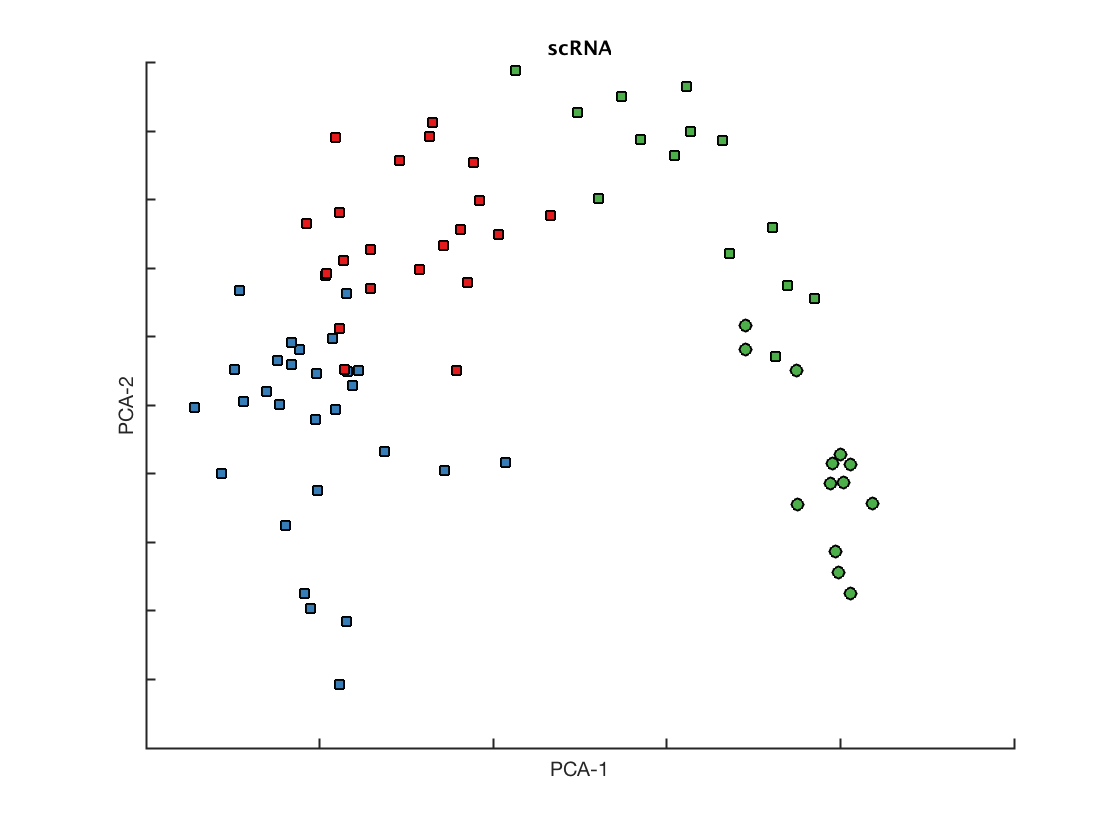

X2a = generate_aggregated_matrix(X2,best_one);
method = 'PCA';
cell_coords1 = reducedDims(X1,Cells,method);
title_name = 'scRNA';
colors = generateColors(length(unique(clust)));
cellVisualizaiton(cell_coords1,clust,term,colors,title_name,method);

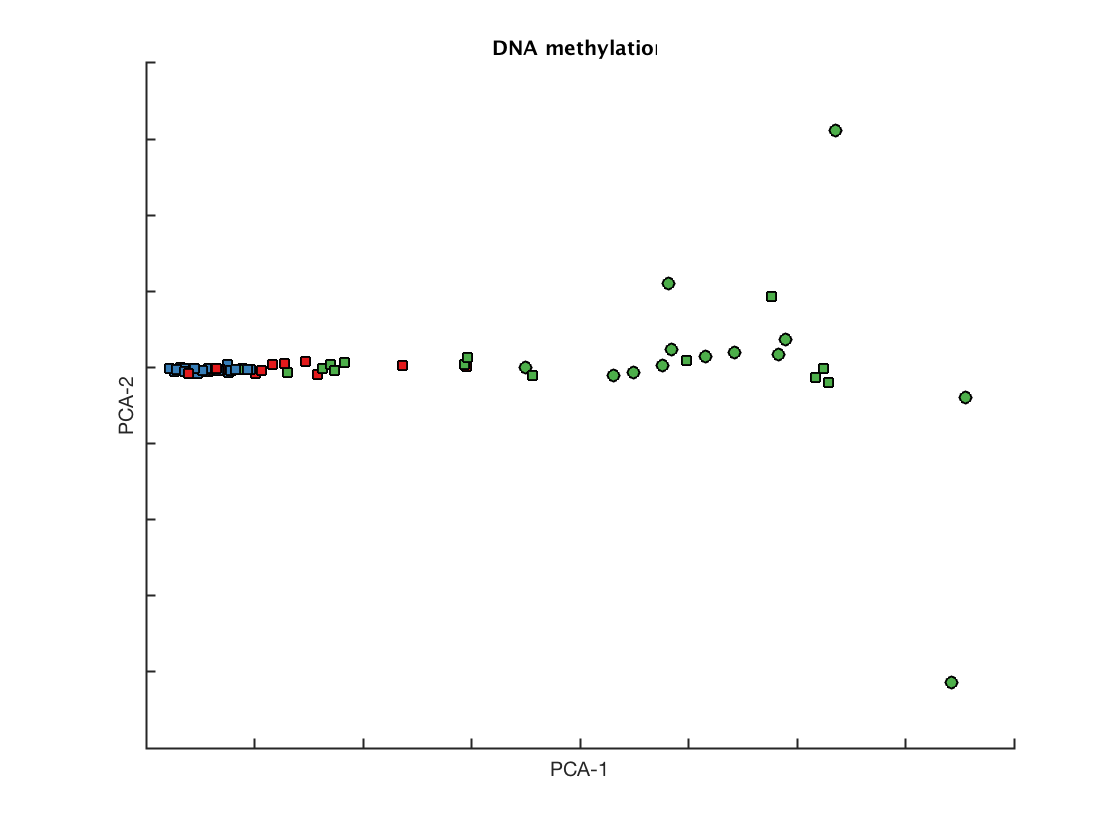

cell_coords2 = reducedDims(X2,Cells,method);
title_name = 'DNA methylation';
cellVisualizaiton(cell_coords2,clust,term,colors,title_name,method);

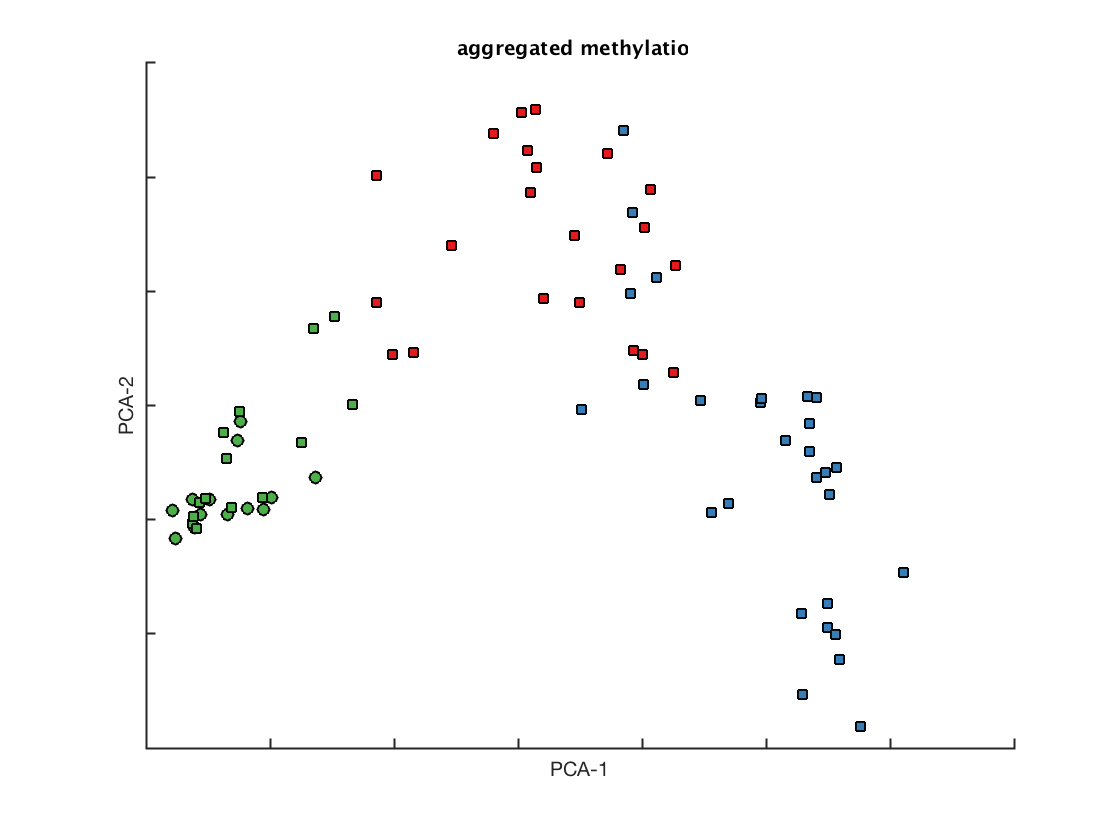

cell_coords3 = reducedDims(X2a,Cells,method);
title_name = 'aggregated methylation';
cellVisualizaiton(cell_coords3,clust,term,colors,title_name,method);

#### 3. Identify factor specific markers

Genes = RNA.Features; Loci = DNA.Features; Cells = RNA.Cells;
W1 = best_one.W1; W2 = best_one.W2; H = best_one.H;

Identify factor specific genes

[factor_genes, ~] = identifyFactorMarkers(X1,W1,H,Genes);

Identify factor specific loci

[factor_loci, ~] = identifyFactorMarkers(X2a,W2,H,Loci);

Identify nearby loci of factor specific genes. 

system_used = 'Mac';
bin = 500000;
species = 'mouse';
factor_genes_nearby_loci = search_nearby_loci(factor_genes,Loci,...
    factor_loci,system_used,bin,species);


Batch submitting query [===============>---------------]  50% eta: 12s
Batch submitting query [======================>--------]  75% eta:  7s
Batch submitting query [===============================] 100% eta:  0s
                                                                      


 Plot the heatmap of factor specific genes, loci and the nearby loci

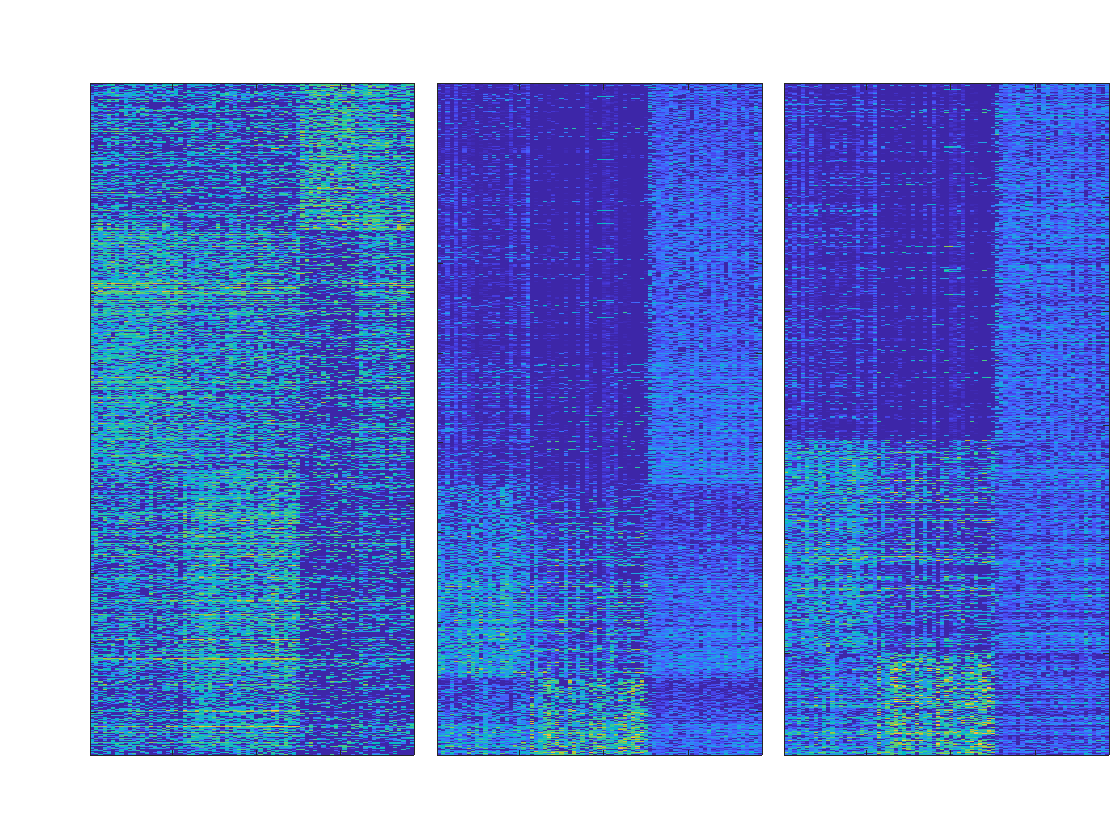

G = []; L = []; N = [];
for i = 1:numCluster
    G = [G;factor_genes{1,i}];
    L = [L;factor_loci{1,i}];
    N = [N; factor_genes_nearby_loci{1,i}];
end
[~,~,ID1] = intersect(G,Genes,'stable');
[~,~,ID2] = intersect(L,Loci,'stable');
[~,~,ID3] = intersect(N,Loci,'stable');
idy = [];
for i = 1:numCluster
    idy = [idy;find(clust == i)];
end
figure;
ha = tight_subplot(1,3,[0.01,0.02],[0.1 0.1],[0.08 0.01]);
axes(ha(1))
imagesc(X1(ID1,idy))
set(gca,'xticklabel',[]);
set(gca,'yticklabel',[]);
axes(ha(2))
imagesc(X2a(ID2,idy))
set(gca,'xticklabel',[]);
set(gca,'yticklabel',[]);
axes(ha(3))
imagesc(X2a(ID3,idy))
set(gca,'xticklabel',[]);
set(gca,'yticklabel',[]);

Plot the rank of selected marker genes

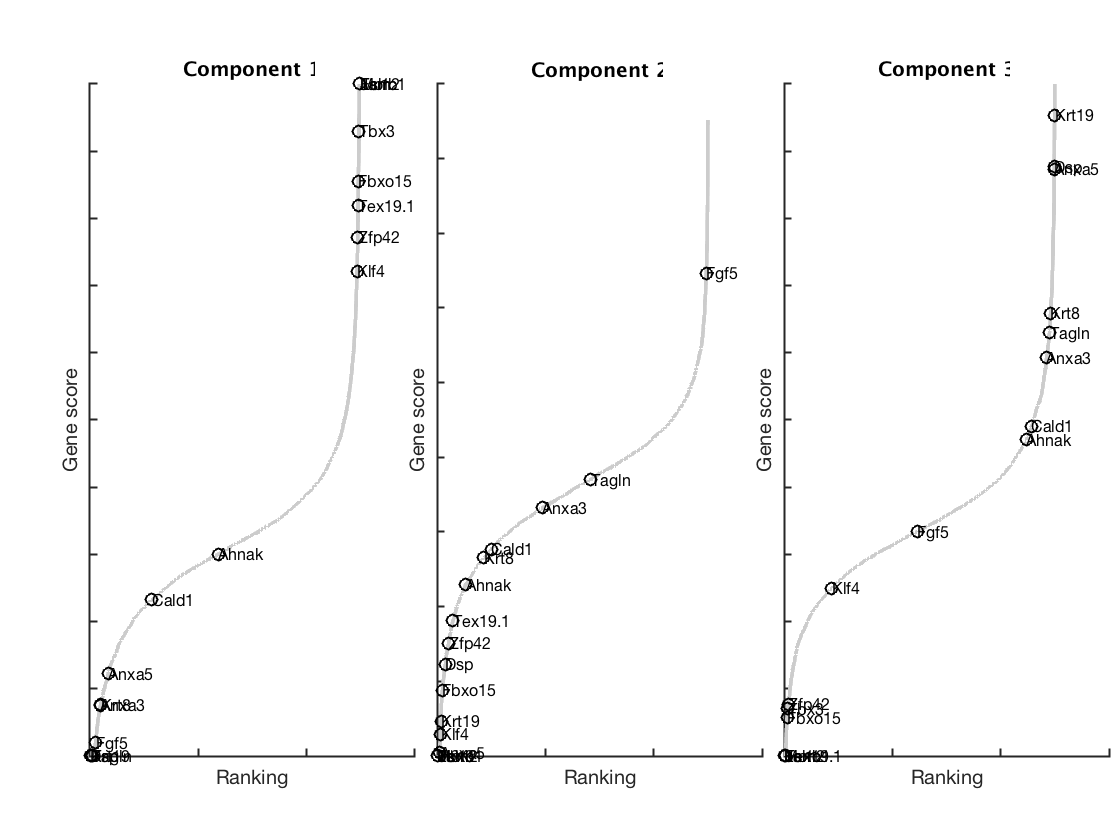

marker_genes = {'Zfp42','Esrrb','Morc1','Fbxo15','Jam2','Klf4','Tcl1','Tbx3',...
    'Tex19.1','Krt8','Cald1','Anxa5','Tagln','Ahnak','Dsp','Anxa3','Krt19',...
    'Fgf5'};
featureRankingPlot(W1,Genes,marker_genes,[],[]);

For each marker gene, identify the promoter, enhancer and cpg loci near it within 500kb

factor_genes_loci = ...
    readtable('./intermediateFiles/factor_genes_loci.txt',...
    'ReadVariableNames',0);
[Marker_genes_near_loci,near_genes_name] = ...
    identify_selected_marker_loci_names(factor_loci,Loci,marker_genes,...
    factor_genes_loci,bin);

Plot the rank of loci near the selected marker genes

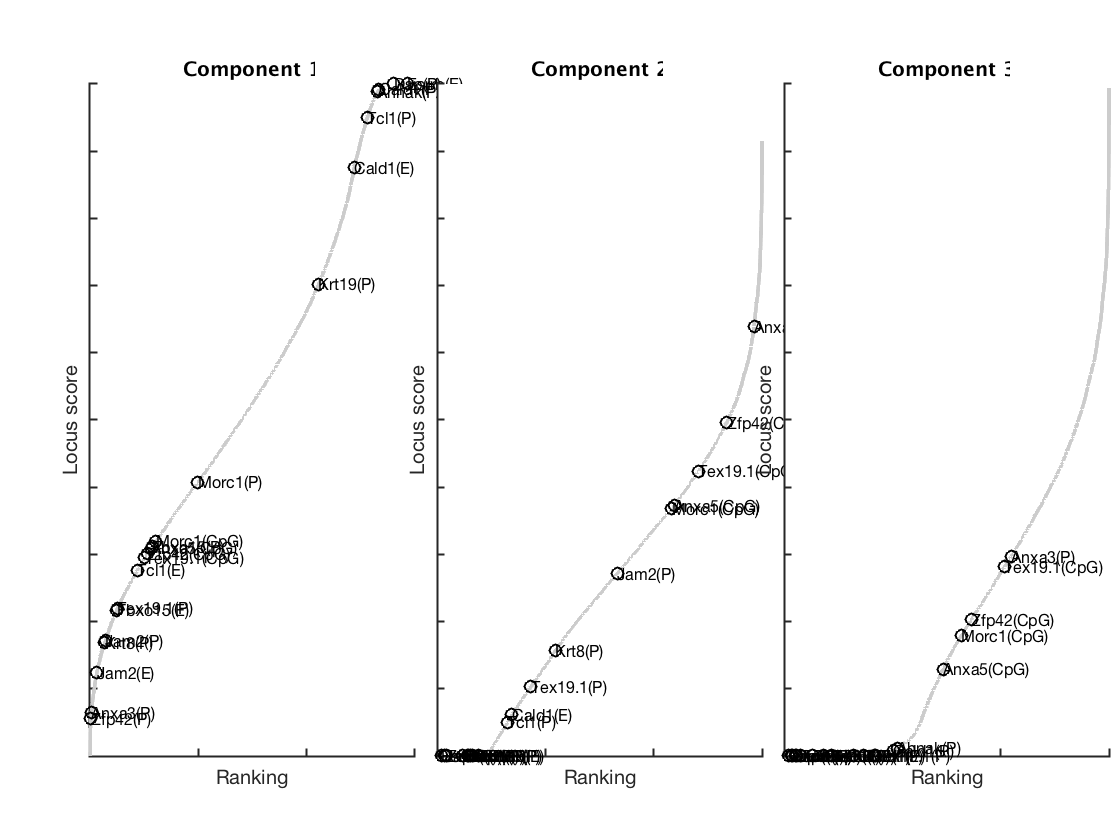

marker_loci = []; marker_loci_names = [];
for i = 1:length(Marker_genes_near_loci)
    marker_loci = [marker_loci;Marker_genes_near_loci{1,i}];
    marker_loci_names = [marker_loci_names;near_genes_name{1,i}];
end
[marker_loci,Index] = unique(marker_loci);
marker_loci_names = marker_loci_names(Index);
featureRankingPlot(W2,Loci,marker_loci,marker_loci_names,[]);

#### 4. Visualize markers across all cells by VscAI

clear RNA DNA;
RNA = array2table(X1,'RowNames',Genes,'VariableNames',Cells);
DNA = array2table(X2,'RowNames',Loci,'VariableNames',Cells);
system_used = 'Mac';
[sample_coords,factor_coords] = getEmbeddings(RNA,DNA,marker_genes,...
    marker_loci,best_one,system_used);

Loading required package: ggplot2
Loading required package: cowplot

Attaching package: ‘cowplot’

The following object is masked from ‘package:ggplot2’:

    ggsave

Loading required package: Matrix
Warning messages:
1: package ‘ggplot2’ was built under R version 3.5.2 
2: package ‘cowplot’ was built under R version 3.5.2 
3: package ‘Matrix’ was built under R version 3.5.2 

Attaching package: ‘swne’

The following object is masked from ‘package:Seurat’:

    ExtractField

Initial stress        : 0.00000
stress after   3 iters: 0.00000


Visualize marker genes across all cells

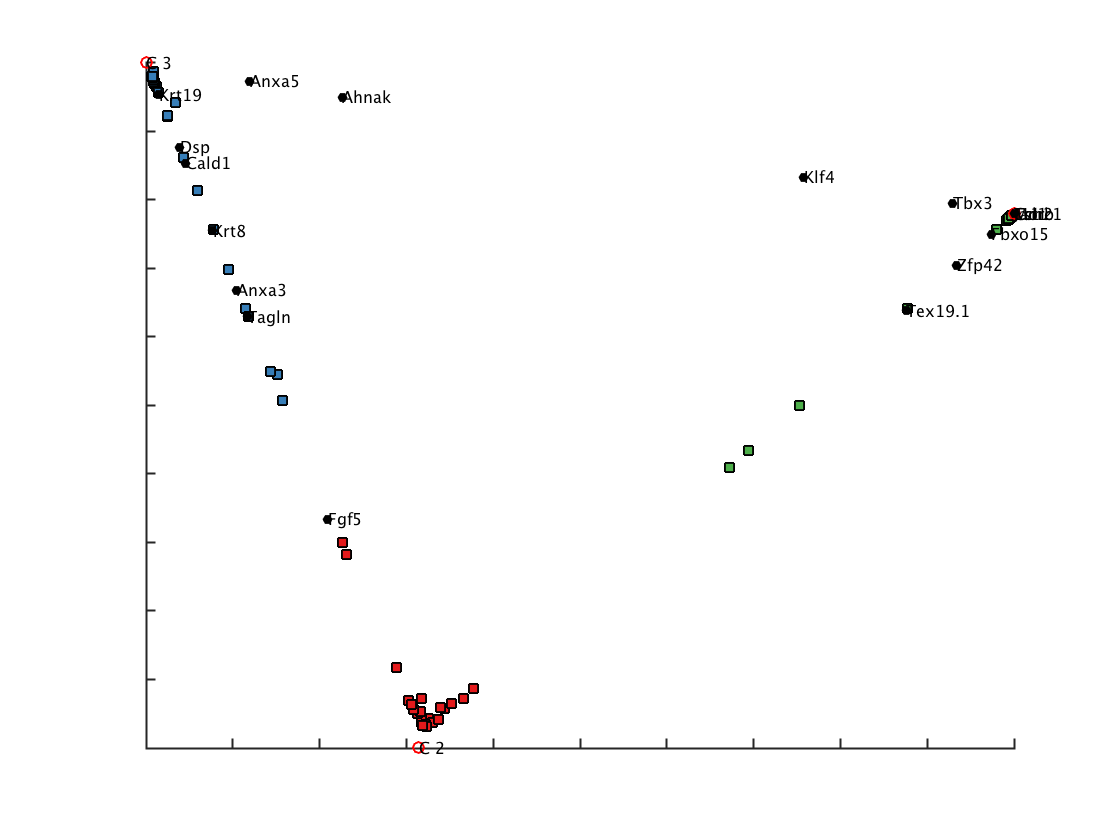

marker_genes_coords = readtable('./intermediateFiles/marker_coords_X1.txt',...
    'ReadRowNames',1);
VscAIplot(sample_coords,factor_coords,marker_genes_coords,[],[],clust,...
    term,[]);

Visualize unmethylated regions of marker genes across all cells

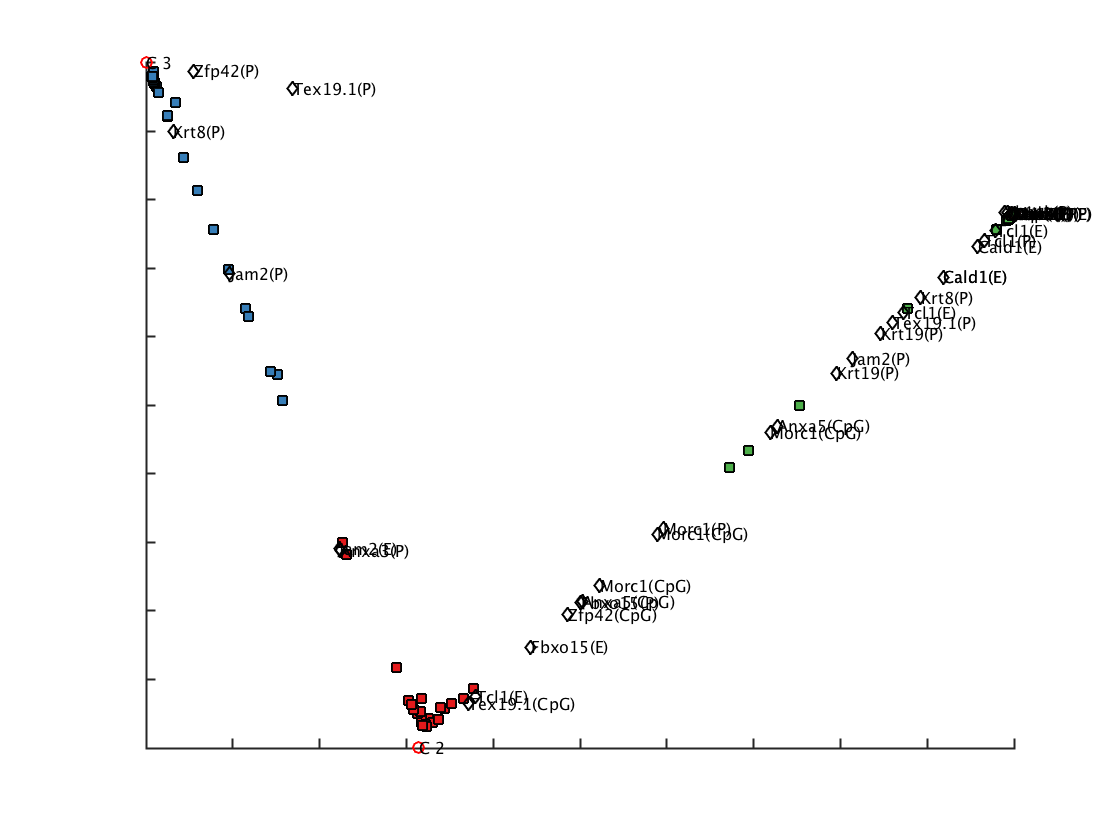

marker_loci_coords = readtable('./intermediateFiles/marker_coords_X2.txt',...
    'ReadRowNames',1);
VscAIplot(sample_coords,factor_coords,[],marker_loci_coords,...
    marker_loci_names,clust,term,[])